# Linear Algebra Lecture Note(08)

## Matrix Inverse

### Code Exercise (08_01)

> Calculating Left Inverse

% % Clear workspace, command window, and close all figures
% clc; clear; close all;
% 
% % Generate a random 40x4 matrix with integer elements from -10 to 10
% T = randi([-10, 10], 40, 4);
% 
% %%%%%%% TODO %%%%%%%
% % Refer to the lecture slide 21
% % Compute the product of T transpose and T
% % Use ''' or 'transpose(matrix)' function
% TtT = ;
% 
% % Compute the inverse of the product
% % Use 'inv(matrix)' function
% TtT_inv = ;
% 
% % Compute the Left inverse matrix
% % Use '*' function
% L = ;
% 
% % Multiply the inverse with the original product to get the identity matrix
% LT = ;
% TL = ;
% %%%%%%%%%%%%%%%%%%%%
% 
% % Visualize the matrices
% figure;
% imagesc(T); % Display the matrix as a color image
% colorbar;        % Show a color scale
% title('Original Matrix T');
% axis([0.5 40 0 40]);     % Make axes square
% 
% figure;
% imagesc(L); % Display the matrix as a color image
% colorbar; % Show a color scale
% title('L');
% axis([0 40 0.5 40]); % Make axes square
% 
% figure;
% imagesc(LT); % Display the matrix as a color image
% colorbar; % Show a color scale
% title('LT');
% axis square; % Make axes square
% 
% figure;
% imagesc(TL); % Display the matrix as a color image
% colorbar; % Show a color scale
% title('TL');
% axis square; % Make axes square

### Code Exercise (08_02)

> Geometric Transformation of Inverse

% %  Generate the points on a circle.
% %  Define the Transformation matrix 𝑇 and inverse matrix 𝑇 −1 .
% %  Check the result of 𝑇𝑃 and 𝑇 −1 𝑇𝑃.
% 
% % Clear workspace, command window, and close all figures
% clc; clear; close all;
% 
% % Define angles 0 to 340 degrees in 20 degree increments
% angles = 0:20:340;
% 
% % Convert degrees to radians for computation
% radians = deg2rad(angles);
% 
% % Create points on a circle with radius 1
% P = [cos(radians); sin(radians)];
% 
% %%%%%%% TODO %%%%%%%
% % Refer to the lecture slide 36
% % Define a transformation matrix T
% % Matrix T must be 2x2 matrix
% T = ; 
% 
% % Apply the transformation to create Q
% Q = ;
% 
% % Calculate U, which should be the same as P
% % Use 'inv(matrix)' function
% U = ;
% %%%%%%%%%%%%%%%%%%%%
% 
% % Visualize the points P, Q, and U on the same plot for comparison
% figure;
% plot(P(1, :), P(2, :), 'bo', 'LineWidth', 2, 'MarkerSize', 10, 'DisplayName', 'Original Points P');
% hold on; % Hold on to plot additional points
% plot(Q(1, :), Q(2, :), 'rx', 'LineWidth', 2, 'MarkerSize', 10, 'DisplayName', 'Transformed Points Q');
% plot(U(1, :), U(2, :), 'g+', 'LineWidth', 2, 'MarkerSize', 10, 'DisplayName', 'Recovered Points U');
% legend show; % Show legend to label point sets
% axis square; % Equal scaling for both axes
% grid on; % Enable grid
% title('P, Q, and U');
% xlabel('X-axis');
% ylabel('Y-axis');
% hold off; % Release the plot

## Assignment Section

### Exercise 1: Hand Made Inverse Algorithm

% % ■ Implement the full-inverse algorithm for a 2 × 2 matrix using matrix elements 𝑎, 𝑏, 𝑐,
% %   and 𝑑. (not using inverse function)
% % ■ Hint: Remember that the determinant of a scalar is its absolute value.
% 
% % Clear workspace, command window, and close all figures
% clc; clear; close all;
% 
% % Assume that input value is [a,b;c,d] (2x2 matrix)
% % then make a function that return a inverse matrix
% % NOTE: Do not use inverse function in MATLAB
% 
% % input1
% a1 = 2;
% b1 = 1;
% c1 = 6;
% d1 = 8;
% 
% % input2
% a2 = 4;
% b2 = 10;
% c2 = 2;
% d2 = 5;
% 
% % Write here (start)
% % Create error when inverse matrix does not exist
% function inverse_matrix = handMadeInverseMatrix(a, b, c, d)
%     % Compute the determinant
% 
%     % Check error
%     if 
%         error('Matrix is not invertible');
%     end
% 
%     % Compute the inverse manually
% 
% end
% % Write here (end)
% 
% % Call the function and store the inverse matrix
% % Display the result
% inv1 = handMadeInverseMatrix(a1,b1,c1,d1);
% disp('Inverse matrix1:');
% disp(inv1);
% inv2 = handMadeInverseMatrix(a2,b2,c2,d2);

### Exercise 2: Implements of Various Matrices

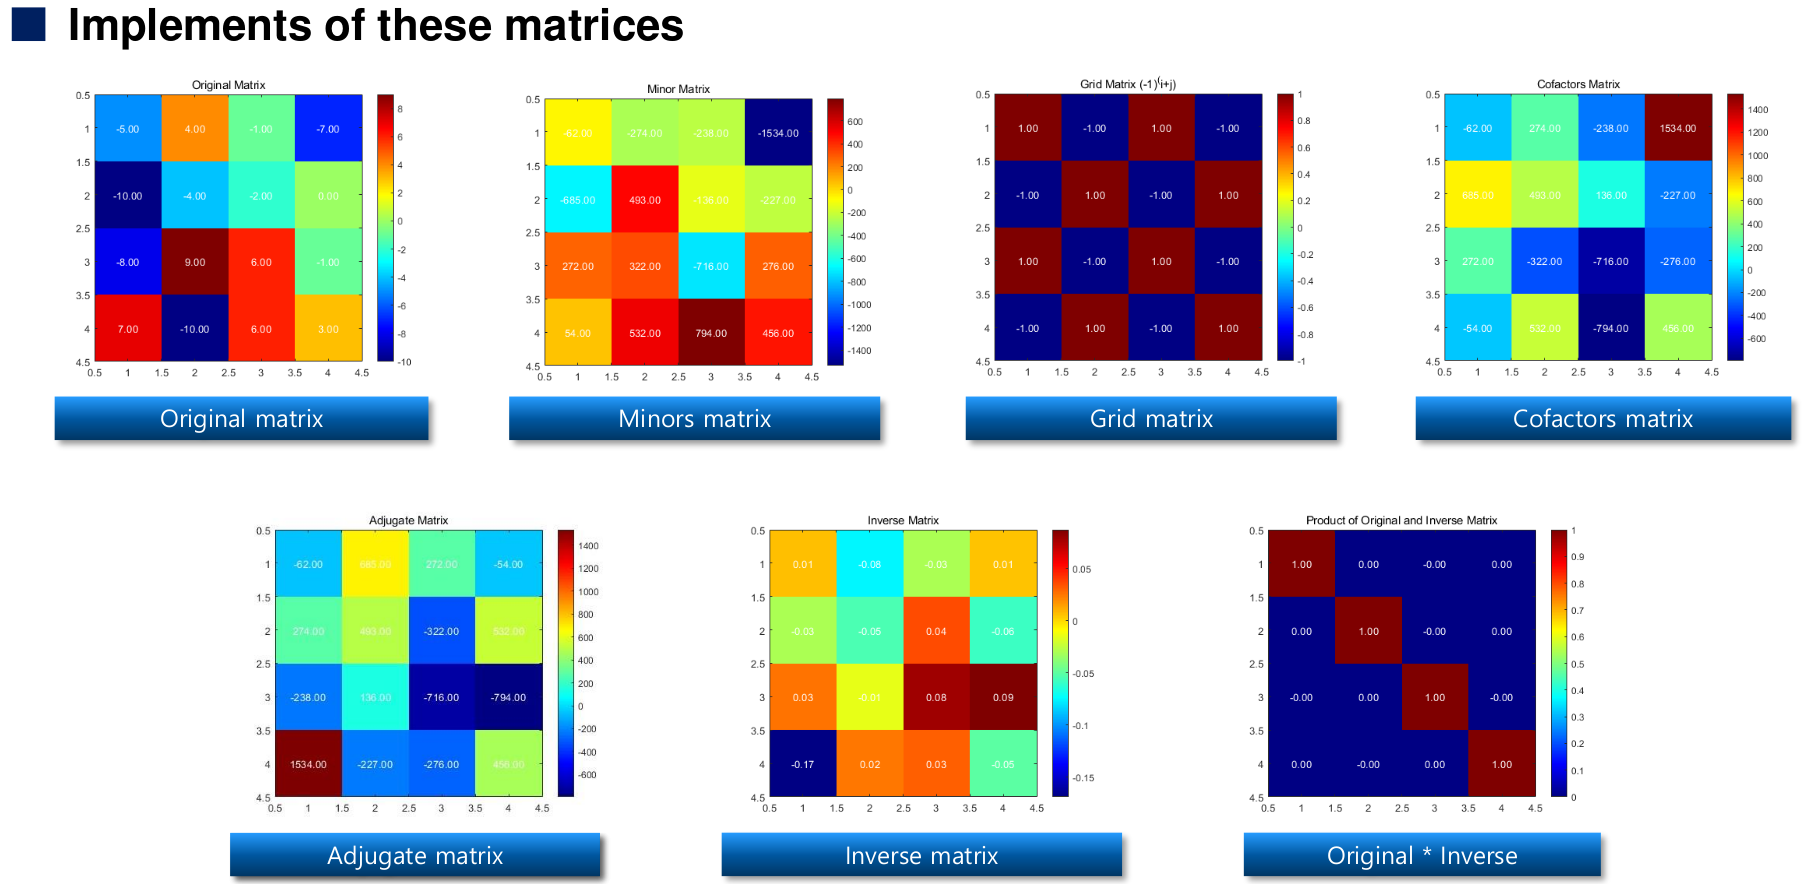

% % Clear workspace, command window, and close all figures
% clc; clear; close all;
% 
% % Create a 4x4 original matrix with integer elements
% originalMatrix = [-5,4,-1,-7;
%                   -10,-4,-2,0;
%                   -8,9,6,-1;
%                   7,-10,6,3];
% 
% % Create a 4x4 grid matrix where elements are (-1)^(i+j)
% [i, j] = meshgrid(1:4, 1:4);
% gridMatrix = (-1).^(i+j);
% 
% % Compute the minor matrix
% minorMatrix = zeros(4);
% for row = 1:4
%     for col = 1:4
%         subMatrix = originalMatrix;
%         subMatrix(row, :) = [];
%         subMatrix(:, col) = [];
%         minorMatrix(row, col) = det(subMatrix);
%     end
% end
% 
% % Write here (start)
% % Refer to the lecture slide 43
% % Compute the cofactors matrix
% % Use '.*' function to compute the cofactorsMatrix
% cofactorsMatrix = ;
% 
% % Check if the matrix is invertible
% determinant = det(originalMatrix);
% if determinant == 0
%     error('The original matrix is singular and does not have an inverse.');
% end
% 
% % Compute the adjugate matrix and inverse matrix of the original matrix
% % Use 'transpose(matrix)' to compute the adjugate matrix
% % Use adjugateMatrix to compute inverse matrix
% adjugateMatrix = ;
% inverseMatrix = ;
% 
% % Compute the product of the original matrix and its inverse
% identityMatrix = ;
% % Write here (end)
% 
% % Visualize all matrices
% visualizeMatrix(originalMatrix, 'Original Matrix');
% visualizeMatrix(minorMatrix, 'Minors Matrix');
% visualizeMatrix(gridMatrix, 'Grid Matrix (-1)^(i+j)');
% visualizeMatrix(cofactorsMatrix, 'Cofactors Matrix');
% visualizeMatrix(adjugateMatrix, 'Adjugate Matrix');
% visualizeMatrix(inverseMatrix, 'Inverse Matrix');
% visualizeMatrix(identityMatrix, 'Product of Original and Inverse Matrix');
% 
% % Function definition : visualize matrix
% function visualizeMatrix(matrix, titleStr)
%     figure;
%     imagesc(matrix);
%     colorbar;
%     title(titleStr);
%     colormap jet;
%     axis square;
%     % Add text annotations for each element
%     for i = 1:size(matrix, 1)
%         for j = 1:size(matrix, 2)
%             text(j, i, num2str(matrix(i, j), '%.2f'), ...
%                 'HorizontalAlignment', 'center', ...
%                 'Color', 'white', 'FontSize', 10);
%         end
%     end
% end